stockdata=readtable('stock_data.csv');
prices=table2array(stockdata(:,3:end));

corr(prices(:,1),prices(:,2));

prices(:,1);

% Finding stocks with max correlation
corrs=zeros(10);
for i=1:10
    for j=1:10
        if i==j continue; end

        corrs(i,j)=corr(prices(:,i),prices(:,j));
    end
end

% GOOG AND TTWO had highest correlation from visual inspection
GOOG=prices(:,3);
TTWO=prices(:,10);

M=60;

% Create returns vector
retGOOG=price2ret(GOOG);
retTTWO=price2ret(TTWO);
N=length(retTTWO);

% Evaluate regression coefficient
alphavec = zeros((N-60),1);
betavec = zeros((N-60),1);
for i = M+1:1:N
[beta,betaint] = regress(retGOOG((i-M):(i-1)),[ones(M,1) retTTWO((i-M):(i-1))]);
alphavec(i-M) = beta(1);
betavec(i-M) = beta(2);
end

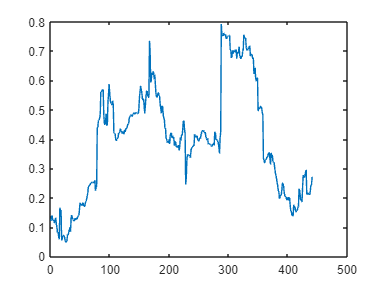

plot(betavec);

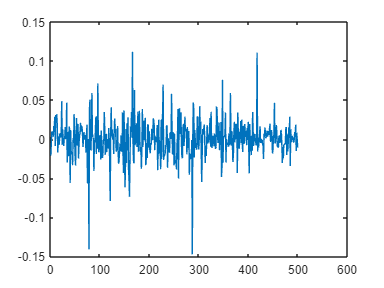

plot(retTTWO);

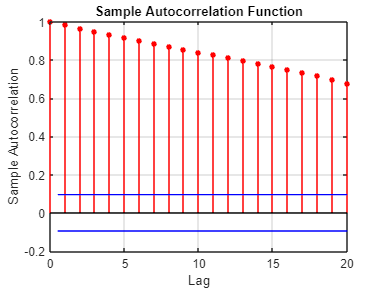

autocorr(betavec);

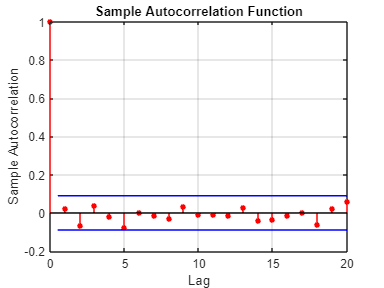

autocorr(retTTWO);

delta_X=retGOOG(M:end-1)-betavec.*retTTWO(M:end-1)-alphavec;
X=zeros(length(delta_X),1);
for k=1:length(delta_X)
    X(k)=sum(delta_X(1:k));
end

data=X;
numTimestepsTrain= 400;
dataTrain=data(1:numTimestepsTrain);
dataTest=data(numTimestepsTrain+1:end);

%%mu = mean(dataTrain);
%%sig = std(dataTrain);

dataTrainStandardized =data;%% (dataTrain - mu) / sig;
%% Normalizing produced worse results
    
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

adsXTrain = arrayDatastore(XTrain);
adsYTrain = arrayDatastore(YTrain);

cdsTrain = combine(adsXTrain,adsYTrain);

deepNetworkDesigner

XTest=dataTest(1:end-1);
YTest=dataTest(2:end);

[net, YPred]=predictAndUpdateState(layers_1,YTest(end));

Incorrect number or types of inputs or outputs for function 'predictAndUpdateState'.


numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end